# Repaso para examen final

## Problema del bungee jumper (caida libre)

A bungee jumper with a** mass** of 68.1 kg leaps from a stationary hot air balloon. Use

 
$$v\left(t\right)=\sqrt{\frac{\mathrm{gm}}{c_d }\mathrm{tanh}\left(\sqrt{\frac{gc_d }{m}}t\right)}$$
 

to compute velocity for the first 12s of free fall. Also determine the terminal velocity that will be attained for an infinitely long cord (or alternatively, the jumpmaster is having a particularly bad day!). Use a drag coefficient of 0.25 kg/m.

g = 9.81;    % m/s^2
m = 68.1;    % kg
cd = 0.25;   % kg/m
tf=12;  %s
h = 1;
[t,v]= calculoVelocidad(0,tf,h,m,cd,g)

t =      0     1     2     3     4     5     6     7     8     9    10    11    12


v =          0    9.8100   19.2667   27.7140   34.7044   40.0930   44.0019   46.7041   48.5065   49.6789   50.4287   50.9030   51.2008


% t = 0:h:tf % vector de 1 renglon y varias columnas
% size(t);
% v = zeros(size(t)) %vector con puros ceros
% for i=1:1:length(v)-1
%     %v(i+1) = v(i) + f(v(i))*h
%     v(i+1) = v(i) + (g-(cd/m)*v(i)^2)*h;
% end
plot(t,v);  

title('Bungee Jumper');
xlabel('t, s');
ylabel('v, m/s');
grid on;
hold on; %para que 2 gráficas aparezcan
velocidadTerminal = sqrt(g*m/cd); %me da la amplitud
cte = sqrt(cd*g/m); 
limite=velocidadTerminal*ones(size(t));
plot(t,limite);
legend('exacta', 'aproximada', 'velocidad terminal');

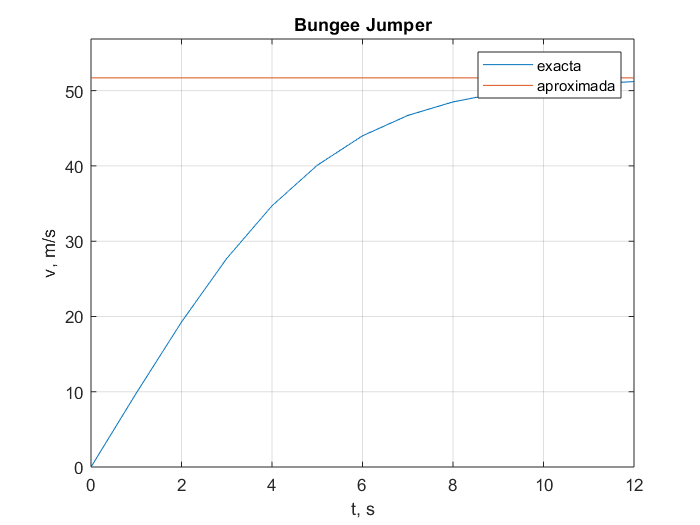

axis([0 tf 0 velocidadTerminal*1.1]);